% Uppgift 1-6
syms z;
X1=2*(z^-1)+4*(z^-2)+5*(z^-3)+3*(z^-4)+2*(z^-5);
iztrans(X1)

$$ans = 2\,\delta_{n-1,0}+4\,\delta_{n-2,0}+5\,\delta_{n-3,0}+3\,\delta_{n-4,0}+2\,\delta_{n-5,0}$$


num = [2 4 5 3 2]

num =      2     4     5     3     2


den = [1 0 0 0 0 0]

den =      1     0     0     0     0     0


sym = dimpulse(num,den,7)

sym =      0
     2
     4
     5
     3
     2
     0


% Uppgift 7-9
num = [1 -1 0];
den = [2 -1 -1];
seq = dimpulse(num, den,5)

seq =     0.5000
   -0.2500
    0.1250
   -0.0625
    0.0312



X2 = (1-(z^-1))/(2-(z^-1)-(z^-2));
iztrans(X2)

$$ans = \frac{{\left(-\frac{1}{2}\right)}^{n}}{2}$$

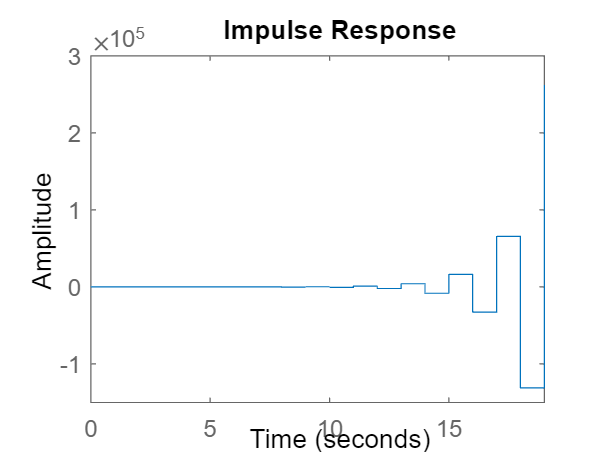

% Uppgift 10
num1 = [1];
den1 = [1 2];
dimpulse(num1, den1,20)

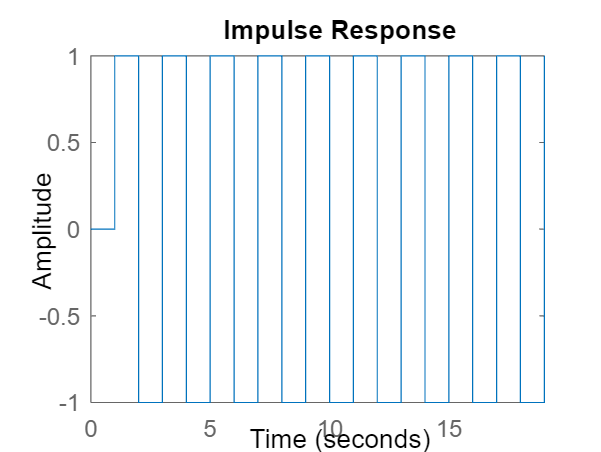


num2 = [1];
den2 = [1 1];
dimpulse(num2, den2,20)

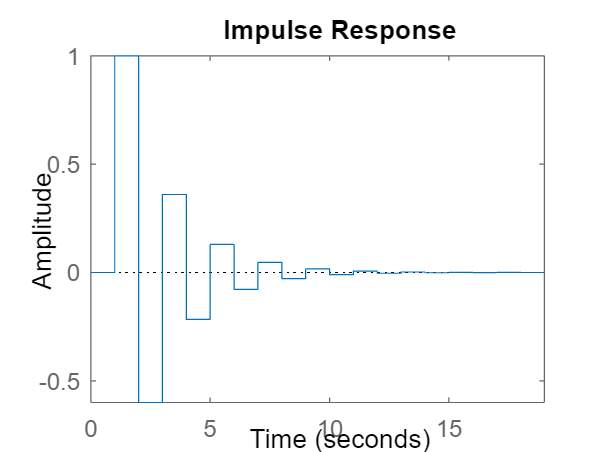


num3 = [1];
den3 = [1 0.6];
dimpulse(num3, den3,20)

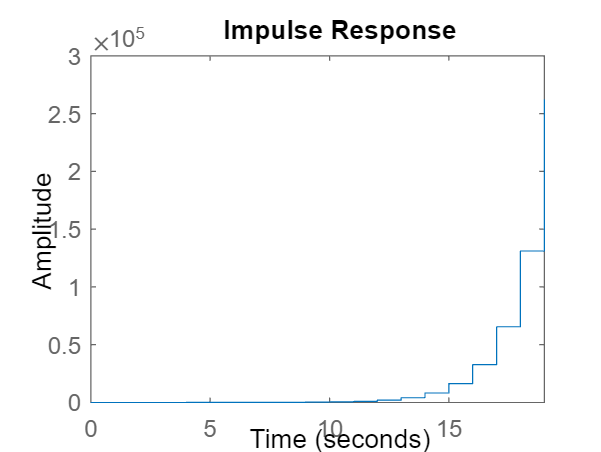


num4 = [1];
den4 = [1 -2];
dimpulse(num4, den4,20)

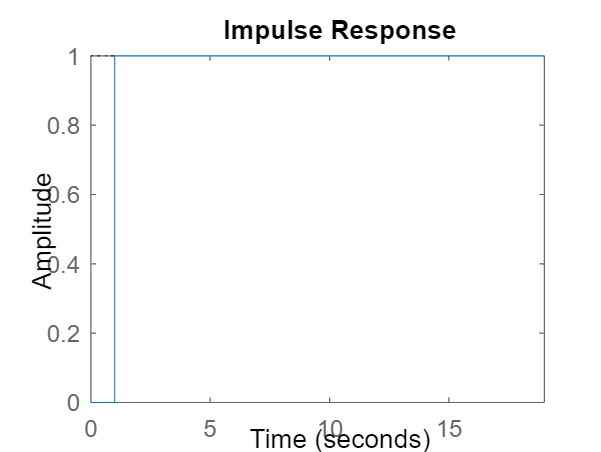


num5 = [1];
den5 = [1 -1];
dimpulse(num5, den5,20)

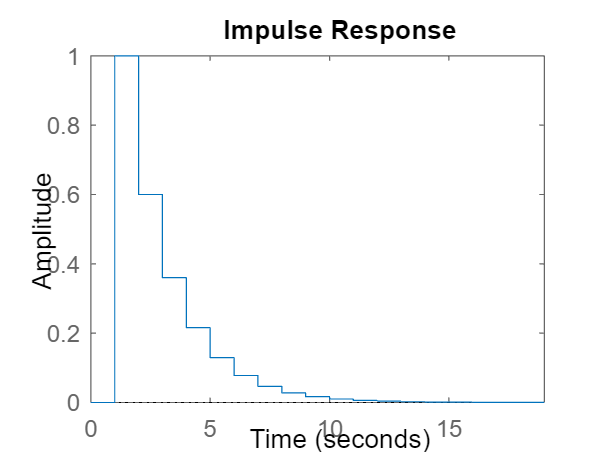


num6 = [1];
den6 = [1 -0.6];
dimpulse(num6, den6,20)

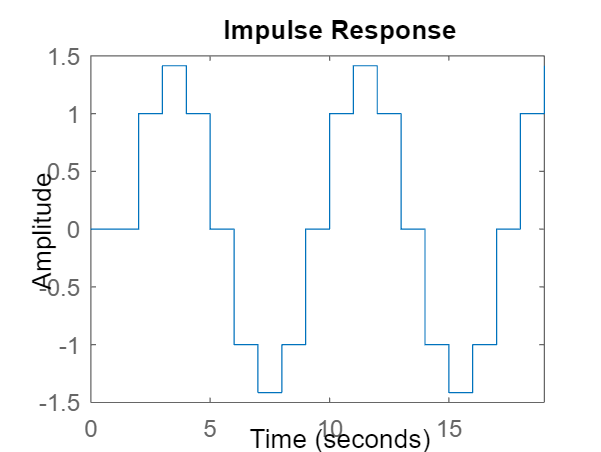


num7 = [1];
den7 = [1 -2/sqrt(2) 1];
dimpulse(num7, den7,20)

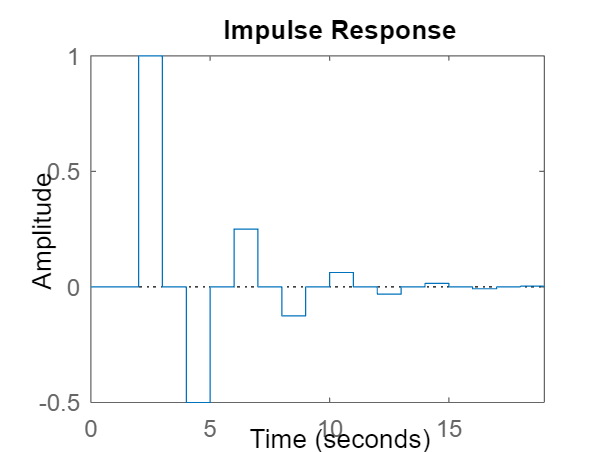


%Innanför komplex
num8 = [1];
den8 = [1 0 1/2];
dimpulse(num8, den8,20)


%Utanför komplex

k= "utanför"

k = "utanför"

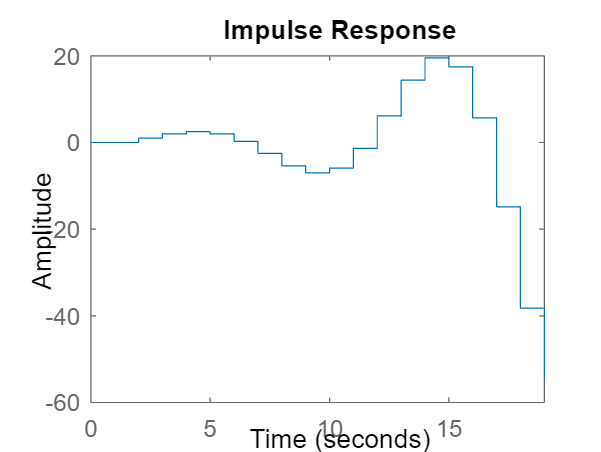

num9 = [1];
den9 = [1 -2 1.5];
dimpulse(num9, den9,20)

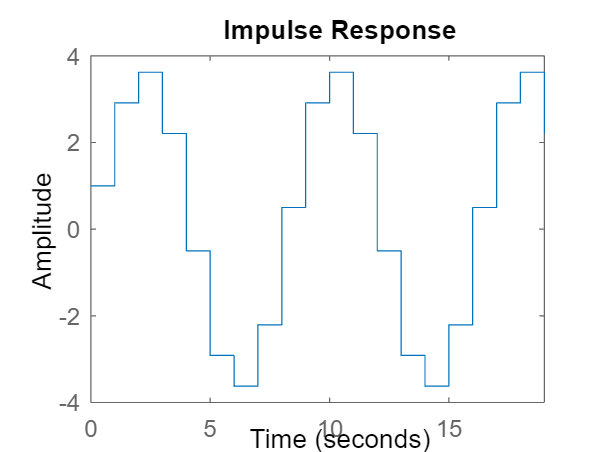

% Med nollställen i z=-1 och z=-2
num7 = [1 1.5 0.5];
den7 = [1 -2/sqrt(2) 1];
dimpulse(num7, den7,20)

% Ljud
[x,fs]=audioread("mooncradle.wav");

num = [1 -2*cos(200/fs) 1];den = [1 0 0];

h=dimpulse(num,den, 300);
y=conv(x,h);